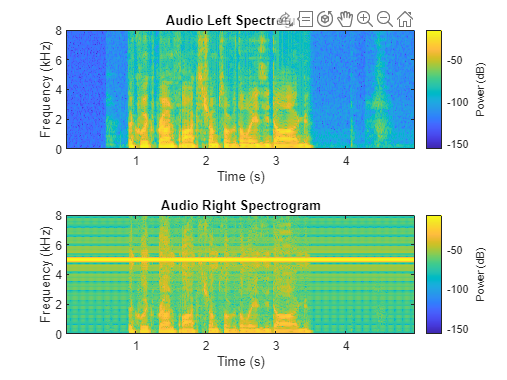

clc
clear all
close all
warning off

%If outputs such as plots are not displaying, restarting MATLAB may fix it
%You may need to change the file paths for audioread and audiowrite

SampleRate = 44100; %Sample Rate of Audio Recording in Hertz

%initializes figures to be used for plotting
%without this, calling PlotAudioTime or PlotAudioSpectrum after the other
%would overwrite the previous plot...
f1=figure;
f2=figure;
%...MATLAB has some weirdness with figures occassionally breaking, you may
%need to add aditional figures

%Generating 5kHz sine
t = linspace(0, 5, SampleRate*5)'; % SampleRate*5 elements linearly spaced going from 0-5
F = 5000; % Sine wave frequency in Hertz
sin5000Hz = sinpi(2*F*t); %Generates sine wave. sinpi includes pi in the function...
% ...automatically and is more accurate than adding a rounded pi within the function
PlotAudioTime(sin5000Hz, SampleRate, f1); %Plots signal over its entire length
PlotAudioTime(sin5000Hz, SampleRate, f1); %Plots signal again...
axis([0 1/5000 -1 1]); %...Sets axis to 1 period of the wave
PlotAudioSpectrogram(sin5000Hz, SampleRate, f2, 8000) %Plots spectrogram of generated sine wave
sound(sin5000Hz, SampleRate); %Plays generated sine wave
audiowrite("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\Kara Giordano SineTone.wav"...
, sin5000Hz, SampleRate) %Writes sine tone to disk
pause(5)

% Generate the 0-8kHz chirp signal using the sinpi functionn
F = linspace(0, 8000, SampleRate*5)'; %Frequency linearly goes from 0-8000Hz
sin8000HzChirp = sinpi(2*cumsum(F)/SampleRate); %Generates chirp
PlotAudioSpectrogram(sin8000HzChirp, SampleRate, f1, 10000) %plots spectrogram
sound(sin8000HzChirp, SampleRate); %Plays chirp
audiowrite("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\Kara Giordano Chirp.wav"...
    , sin8000HzChirp, SampleRate) %Writes chirp to disk
pause(5)

%Generating 5 CETK tones
[AudioData, SampleRate] = audioread("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\CETK 5 Tones.wav");
PlotAudioSpectrogram(AudioData, 44100,f1, 8000) 

[Freqs, Powers] = GetFreqPwr(AudioData, SampleRate, 1, 16650);
Note1 = SineGen(Freqs, Powers, 16650, SampleRate);

[Freqs, Powers] = GetFreqPwr(AudioData, SampleRate, 16651, 38700);
Note2 = SineGen(Freqs, Powers, 22050, SampleRate);

[Freqs, Powers] = GetFreqPwr(AudioData, SampleRate, 38701, 71800);
Note3 = SineGen(Freqs, Powers, 33100, SampleRate);
t = linspace(1, 0.1, 71800-60750)'; %Linearly spaced vector from 1 to 0.1 in 71800-60750 samples
t = paddata(t, size(Note3,1), FillValue=1, Side="leading"); %Pads t with 1s to equal length of Note5
Note3 = t.*Note3; %Multiply Note3 by t for attenuation

[Freqs, Powers] = GetFreqPwr(AudioData, SampleRate, 71801, 93800);
Note4 = SineGen(Freqs, Powers, 22000, SampleRate);
t = linspace(1, 0.1, 93800-86500)'; %Linearly spaced vector from 1 to 0.1 in 93800-86500 samples
t = paddata(t, size(Note4,1), FillValue=1, Side="leading"); %Pads t with 1s to equal length of Note4
Note4 = t.*Note4; %Multiply Note4 by t for attenuation

[Freqs, Powers] = GetFreqPwr(AudioData, SampleRate, 93801, 178000);
Note5 = SineGen(Freqs, Powers, 84200, SampleRate);
t = linspace(1, 0.1, 1000)'; %Linearly spaced vector from 1 to 0.1 in 1000 samples
t = paddata(t, 61000, FillValue=1, Side="leading"); %
t = paddata(t, size(Note5,1), FillValue=0.1, Side="trailing");
Note5=t.*Note5;

WavOut = cat(1,[Note1;Note2;Note3;Note4;Note5]); %Puts each note into 1 vector one after another
PlotAudioTime(WavOut, SampleRate, f1);
PlotAudioSpectrogram(WavOut, SampleRate, f2, 8000);
sound(WavOut, SampleRate); %Plays cetk tones
audiowrite("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\Kara Giordano cetk.wav", WavOut, SampleRate)
pause(4.5)


%Speech file + sine wave
[AudioData, SampleRate] = audioread("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\TQBF Jumps Over Lazy Dog.wav");
AudioData = AudioData + sin5000Hz;
PlotAudioSpectrogram(AudioData, SampleRate, f1, 8000)
sound(AudioData, SampleRate);
audiowrite("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\speechsine.wav", AudioData, SampleRate)
pause(5)


%Make lowpass iir filter and filter speechsine file
LPfilter = designfilt('lowpassiir','FilterOrder',8, ...
    'PassbandFrequency',4000,'PassbandRipple',1, ...
    'StopbandAttenuation',60,'SampleRate',44100);
fvtool(LPfilter) %Plot frequency response of filter
AudioData = filter(LPfilter, AudioData); %Put AudioData through filter

PlotAudioSpectrogram(AudioData, SampleRate, f2, 8000) %Plot filtered data
sound(AudioData, SampleRate);
audiowrite("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\filteredspeechsine.wav", AudioData, SampleRate)
pause(5)


%Left channel speech file, right channel speechsine file
AudioData = zeros(size(sin5000Hz,1), 2);
[AudioData(:,1), SampleRate] = audioread("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\TQBF Jumps Over Lazy Dog.wav");
[AudioData(:,2), SampleRate] = audioread("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\speechsine.wav");
PlotAudioSpectrogram(AudioData, SampleRate, f2, 8000)

sound(AudioData, SampleRate)
audiowrite("C:\Users\ngior\Documents\Class Assignments & Files\ECE 2312 C24\Project 2\stereospeechsine.wav", AudioData, SampleRate);
pause(5)

function OutWave = SineGen (F, Pwr, SampleLength, Fs)
t = linspace(0, SampleLength/Fs, SampleLength)';
Wave = zeros(SampleLength, 8); %Samplelength x 8 matrix of zeros
    for v=1:8
    Wave(:,v) = Pwr(v, 1) * sinpi(2*F(v, 1)*t); %Each column of the matrix, v, is the frequency at position v,1 in F multiplied by its amplitude
    end
Wave = sum(Wave,2); %Sums each vector in Wave matrix
%Adding slight attenuation at beginning and end of wave...
t = linspace(0, 1, 100)'; 
t = paddata(t, SampleLength, FillValue=1);
Wave = Wave.*t;
t = linspace(1, 0, 100)';
t = paddata(t, SampleLength, FillValue=1, Side="leading");
Wave = Wave.*t;
%...prevents pops and clicking when switching notes
OutWave = 2*((Wave-min(Wave))/ (max(Wave) - min(Wave)))-1; %Normalizes output for max. amplitude to be +/-1
end

function [F, Pwr] =  GetFreqPwr(Audio, Fs, SampleStart, SampleEnd)
    scope = spectrumAnalyzer(SampleRate = Fs,...
         AveragingMethod = "vbw", PlotAsTwoSidedSpectrum = false,...
         FrequencySpan = "start-and-stop-frequencies", StartFrequency = 0,...
         StopFrequency = 8000); %Creates spectrumAnalyzer obect with specified parameters
    scope.PeakFinder.Enabled = true; %Enables peak finding
    scope.PeakFinder.LabelPeaks = true; %Enables peak finder labels
    scope.PeakFinder.NumPeaks = 8; %Sets number of peaks to be found
    
    t = SampleStart:SampleEnd; %Integer vector from beginning to end of sample
    scope(Audio(t,:)); %Run the spectrum analyzer on the audio signal
    data = getMeasurementsData(scope); %Creates table of measurements of the peaks
    F = data.PeakFinder.Frequency; %Gets the frequency values from the peakfinder
    Pwr = data.PeakFinder.Value; %Gets the power values in dB from the peakfinder
    Pwr = 10.^(Pwr/10); %Converts dB power to a linear
end

function PlotAudioTime (Audio, Fs, fig)
N=length(Audio);
t = linspace(0, N/Fs, N);
figure(fig);
    if size(Audio, 2) == 1
        plot(t, Audio)
        xlabel('Time, (s)')
        ylabel('Amplitude')
        title('Mono Audio Signal')
        grid on
    elseif size(Audio, 2) == 2
        tiledlayout(2, 1);
        ax1=nexttile;
        plot(t, Audio(:, 1))
        title(ax1, 'Audio Signal Left')
        ylabel(ax1, 'Amplitude')
        xlabel(ax1, 'Time (s)')
        grid on
        ax2=nexttile;
        plot(t, Audio(:, 2))
        title(ax2, 'Audio Signal Right')
        ylabel(ax2, 'Amplitude')
        xlabel(ax2, 'Time (s)')
        grid on
    end
end

function PlotAudioSpectrogram(Audio, Fs, fig, FMax)
figure(fig);
F=linspace(0, FMax, 200);
    if size(Audio, 2) == 1
        spectrogram(Audio, hamming(512), 128, F, Fs,'yaxis','power')
        title('Mono Audio Spectrogram')
    elseif size(Audio, 2) == 2
        tiledlayout(2, 1);
        nexttile
        spectrogram(Audio(:, 1), hamming(512), 128, F, Fs, 'yaxis', 'power')
        title('Audio Left Spectrogram')
        nexttile
        spectrogram(Audio(:, 2), hamming(512), 128, F, Fs, 'yaxis', 'power')
        title('Audio Right Spectrogram')
    end
end